mass = 3;

Y = 0.025;       % Bump height in m
r = 0.2032;     % minimum tyre radius in m (8 inch = 0.2032 m)
v = 8.33;          % max bike velocity in m.s^-1 (7 ms = 15.5 mph = 25.2 kmh)

y_0 = r - Y;
x_0 = sqrt(r^2 - y_0^2);
time = x_0/v

time = 0.0117

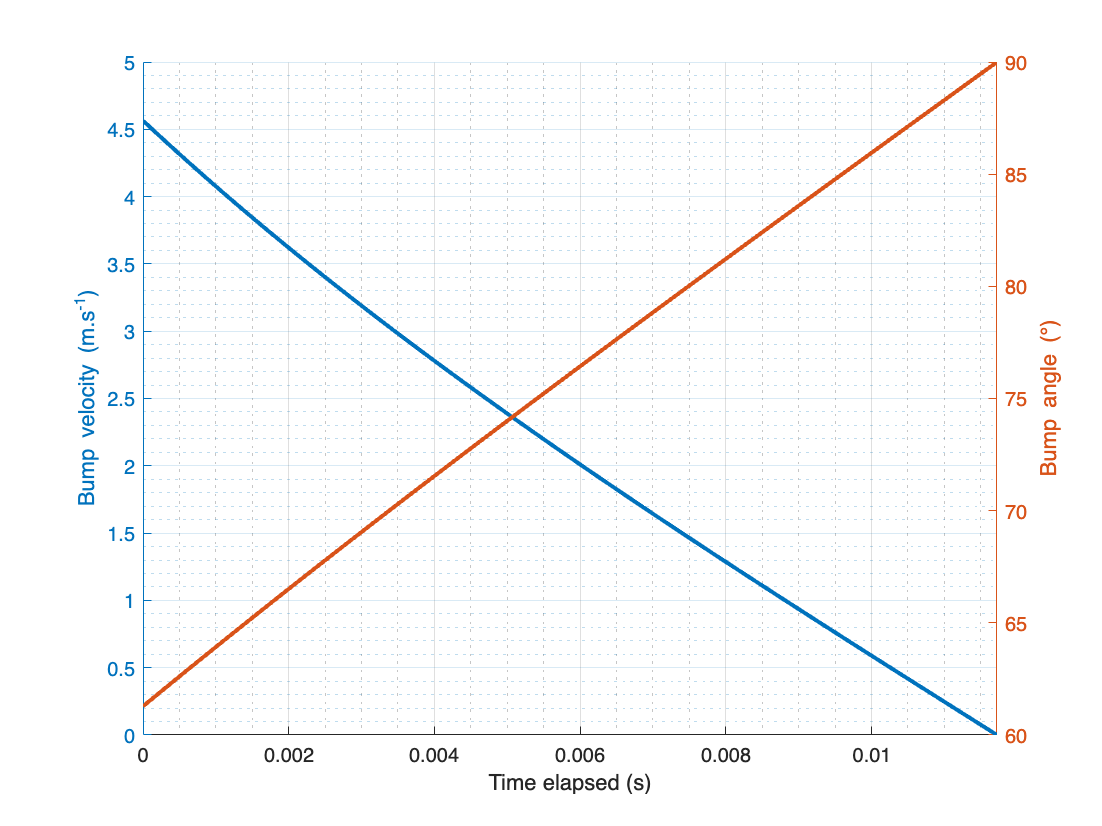


t_vector = linspace(0,time);

x = x_0 - v.*t_vector;

v_bump = v*x./(sqrt(r^2 - x.^2));
angle_bump_rad = acos(x/r);
angle_bump = rad2deg(angle_bump_rad);


% Bump velocity and angle
hold on
yyaxis left
plot(t_vector,v_bump,LineWidth=2)
grid on
grid minor
xlabel("Time elapsed (s)")
ylabel("Bump velocity (m.s^{-1})")
yyaxis right
plot(t_vector,angle_bump,LineWidth=2)
ylabel("Bump angle ({\circ})")
xlim([0 time])

cla reset

F_v = mass*(v_bump.^2)./(2*Y)

F_v = 1.0e+03 *

    1.2501    1.2176    1.1859    1.1548    1.1244    1.0947    1.0656    1.0371    1.0092    0.9820    0.9553    0.9292    0.9036    0.8786    0.8541    0.8302    0.8067    0.7838    0.7613    0.7393    0.7178    0.6967    0.6760    0.6558    0.6361    0.6167    0.5978    0.5793    0.5611    0.5434    0.5260    0.5090    0.4924    0.4762    0.4603    0.4447    0.4295    0.4146    0.4001    0.3859    0.3720    0.3584    0.3451    0.3322    0.3195    0.3071    0.2951    0.2833    0.2718    0.2606


F_t = F_v./sin(angle_bump_rad)

F_t = 1.0e+03 *

    1.4255    1.3843    1.3442    1.3052    1.2672    1.2302    1.1942    1.1591    1.1249    1.0917    1.0592    1.0277    0.9969    0.9669    0.9377    0.9092    0.8814    0.8543    0.8280    0.8022    0.7772    0.7527    0.7289    0.7056    0.6829    0.6608    0.6393    0.6183    0.5978    0.5778    0.5583    0.5393    0.5207    0.5027    0.4850    0.4679    0.4511    0.4348    0.4189    0.4034    0.3882    0.3735    0.3591    0.3452    0.3315    0.3183    0.3054    0.2928    0.2805    0.2686


F_h = F_t.*cos(angle_bump_rad)

F_h =   685.0136  658.4943  632.8955  608.1846  584.3304  561.3028  539.0730  517.6136  496.8980  476.9008  457.5978  438.9654  420.9812  403.6237  386.8719  370.7060  355.1067  340.0556  325.5347  311.5270  298.0159  284.9856  272.4206  260.3062  248.6281  237.3726  226.5263  216.0764  206.0105  196.3166  186.9833  177.9992  169.3536  161.0360  153.0363  145.3446  137.9516  130.8480  124.0249  117.4737  111.1860  105.1537   99.3690   93.8242   88.5120   83.4250   78.5564   73.8993   69.4471   65.1935


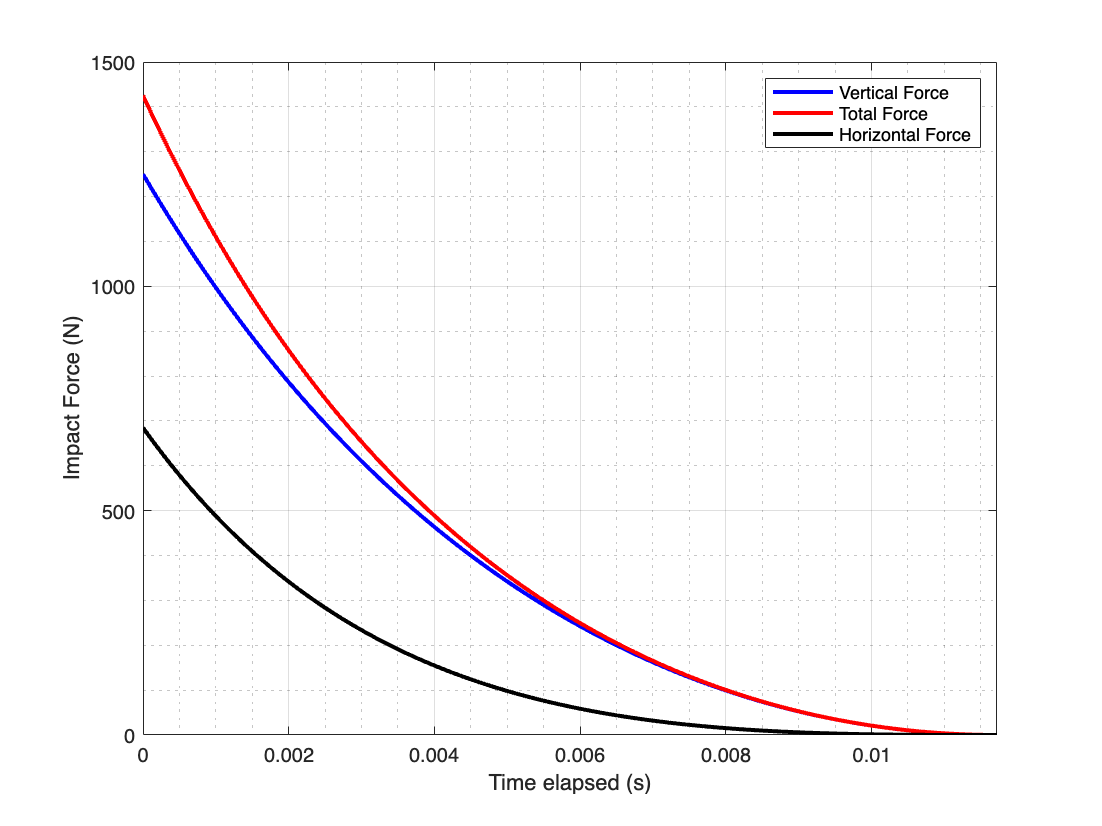


plot(t_vector,F_v,LineStyle="-",Color="b",LineWidth=2)
hold on
plot(t_vector,F_t,LineStyle="-",Color="r",LineWidth=2)
plot(t_vector,F_h,LineStyle="-",Color="k",LineWidth=2)
grid on
grid minor
xlim([0 time])
xlabel("Time elapsed (s)")
ylabel("Impact Force (N)")
legend("Vertical Force", "Total Force", "Horizontal Force")